# Create an array of functions scheduled to run in background

In the previous exercise we have given a quiz to one single student evaluated by an available MATLAB worker acting as a proctor. 

In this exercise instead, we are giving the same quiz to 20 students, using, as before, the function `GiveQuiz`

function [quiztime, passed] = GiveQuiz(graderange)
% GRADERANGE is a 1x2 vector [low high] range of grades

% Each student takes a random amount of time to take the quiz
% (up to 5 "minutes")
quiztime = 5 * rand;
pause(quiztime)

% Generate a uniformly distributed pseudorandom score in the grade range
% (e.g., 49 to 100)
grade = randi(graderange);
passed = grade>70;

end

To give the quiz to 20 students we can call `parfeval` inside a for loop whose loop index goes from 1 to 20  (the students).  The for loop creates an array  of Futures (FevalFuture array)  that will run onto the available workers. The next Future in the array runs on the next available worker. 

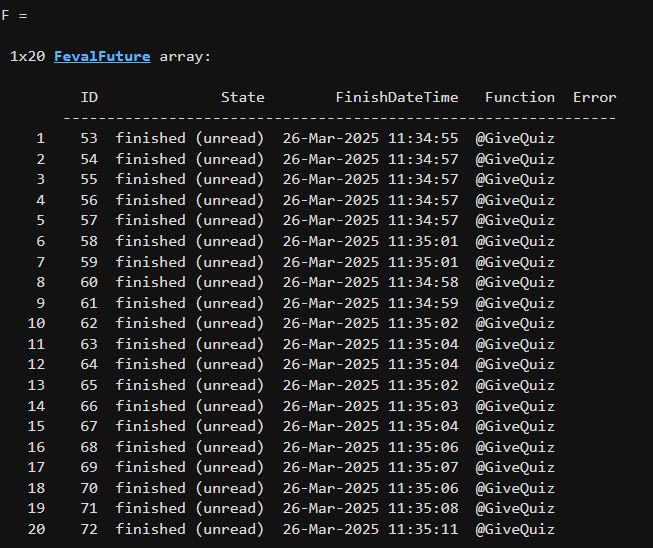

*Example of FevalFuture array*

nStudents = 50;
gradeRange = [49 100]; 

% TODO: use parfeval inside a for loop to create the FevalFuture array F
for i = 1:nStudents
    F(i) = parfeval(@GiveQuiz, 2, gradeRange); 
end

▶️ Run this section to display the array of Futures `F` 

F

As the grades come back we can fetch the quiz results using [`fetchNext`](https://www.mathworks.com/help/releases/R2025a/matlab/ref/parallel.fevalfuture.fetchnext.html).

First preallocate the vectors that will contain the student index, the timing, and the failed (logical variable). Then, write a for loop whose loop index goes from 1 to 20. Inside the for loop use `fetchNext` to assign the Future outputs to the array elements. 

% TODO: use fetchnext to retrieve the outputs from the background pool. 
studIdx = nan(nStudents,1);
quiztime = nan(nStudents,1);
passed = nan(nStudents,1);
for i = 1:nStudents
    [studIdx(i), quiztime(i), passed(i)] = fetchNext(F); 
    b = bar(quiztime);
    b.FaceColor = 'flat';
    for j = 1:i
        if ~passed(j)
            b.CData(j,:) = [1 0 0];
        end
    end
    drawnow
end

Create a table with the final results. 

% TODO: create the FinalResults table 
[quiztime, passed] = fetchOutputs(F);
FinalResults = table(quiztime, passed)
b = bar(quiztime);
b.FaceColor = 'flat';
for i = 1:numel(quiztime)
    if ~passed(i)
        b.CData(i,:) = [1 0 0];
    end
end

**▶️ Clear the workspace**

clear

*Copyright 2025 The MathWorks, Inc.*